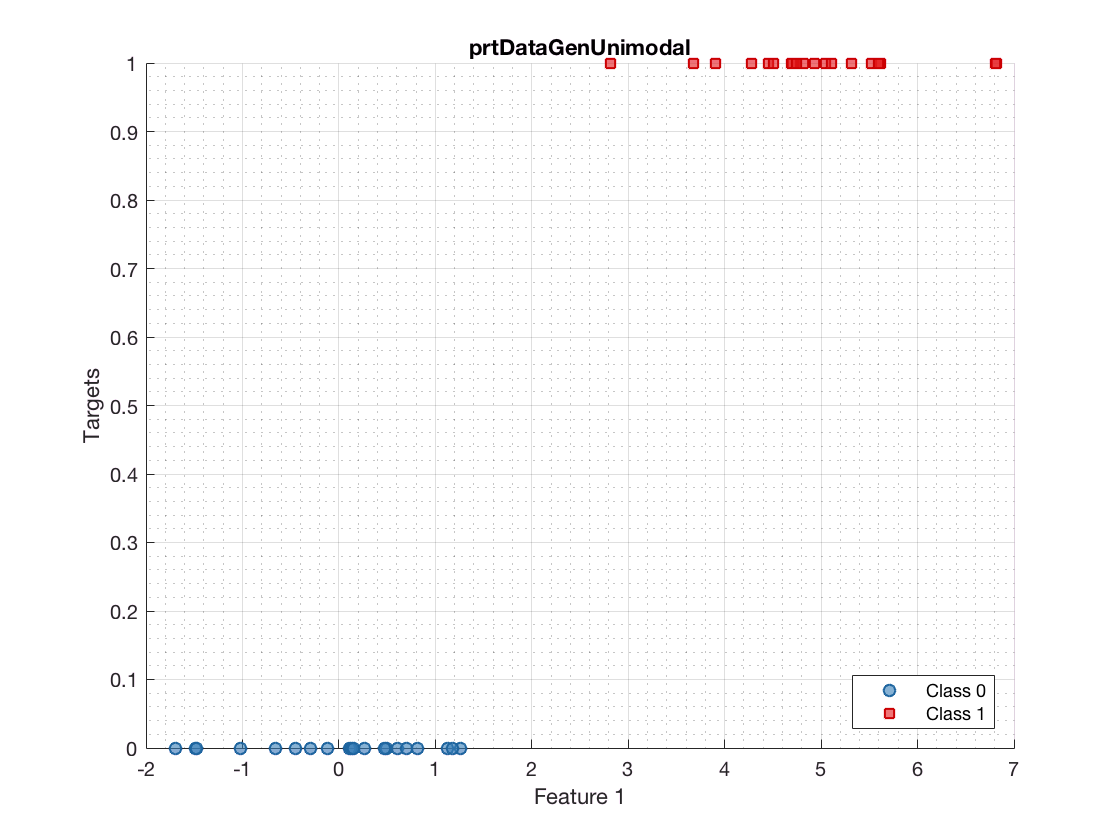

ds = prtDataGenUnimodal(20,0,5,1,1);
plot(ds)

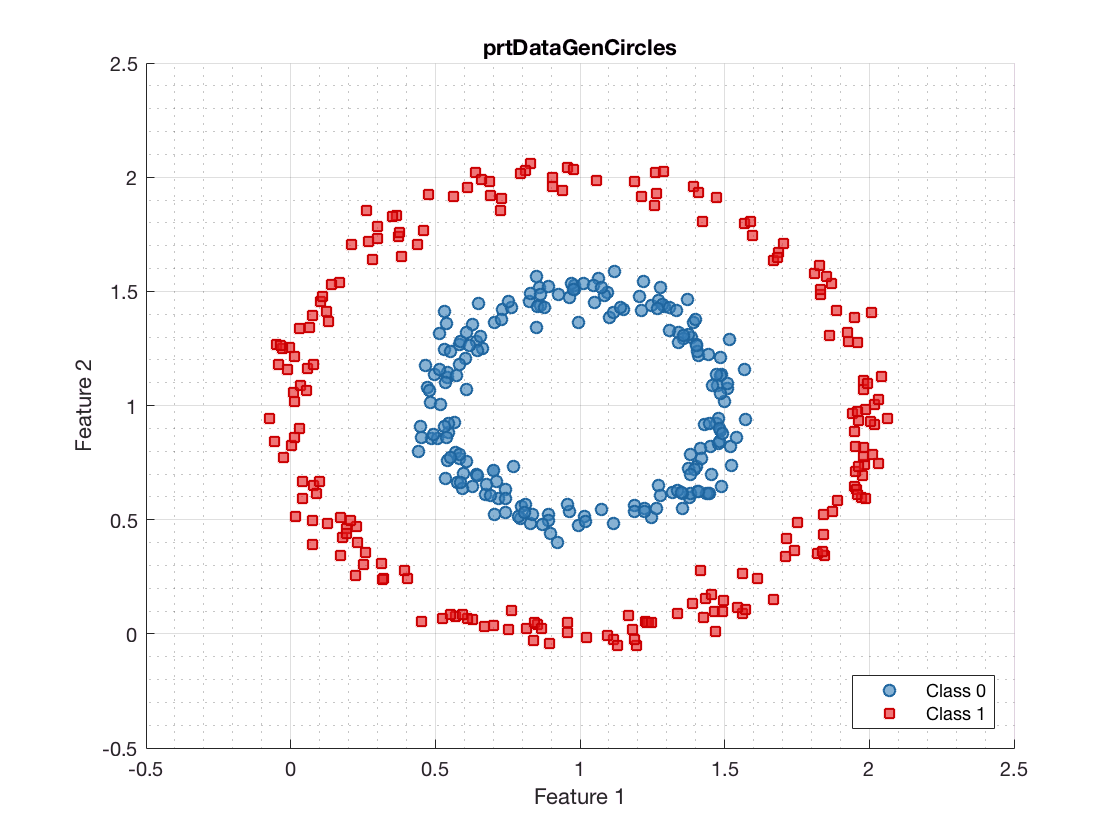

ds_train = prtDataGenCircles;
ds_test = prtDataGenCircles;
plot(ds_test)

cls = prtClassKnn;
cls_trained = cls.train(ds_train)

cls_trained =   prtClassKnn with properties:

                    name: 'K-Nearest Neighbor'
        nameAbbreviation: 'KNN'
            isNativeMary: 1
                       k: 3
        distanceFunction: @(x1,x2)prtDistanceEuclidean(x1,x2)
        twoClassParadigm: 'binary'
         internalDecider: []
            isSupervised: 1
    isCrossValidateValid: 1
          verboseStorage: 1
         showProgressBar: 1
               isTrained: 1
          dataSetSummary: [1×1 struct]
                 dataSet: [1×1 prtDataSetClass]
                userData: [1×1 struct]


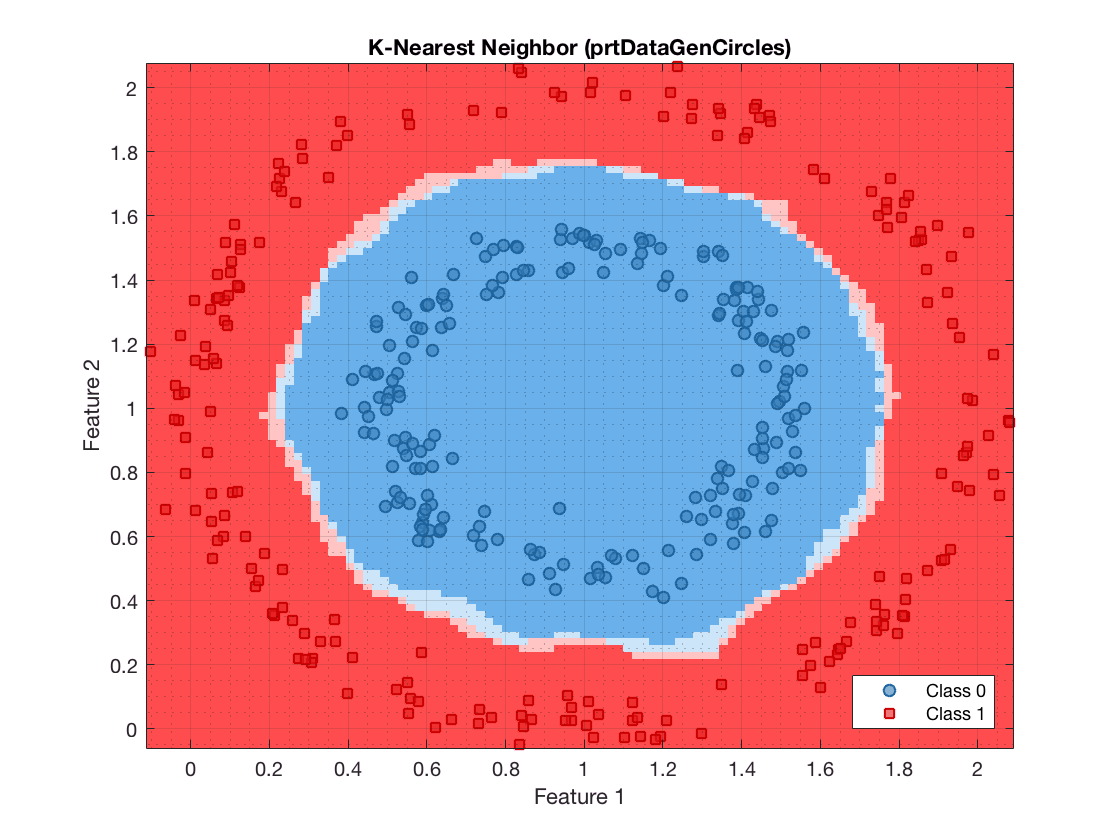

results = cls_trained.run(ds_test);
plot(cls_trained)

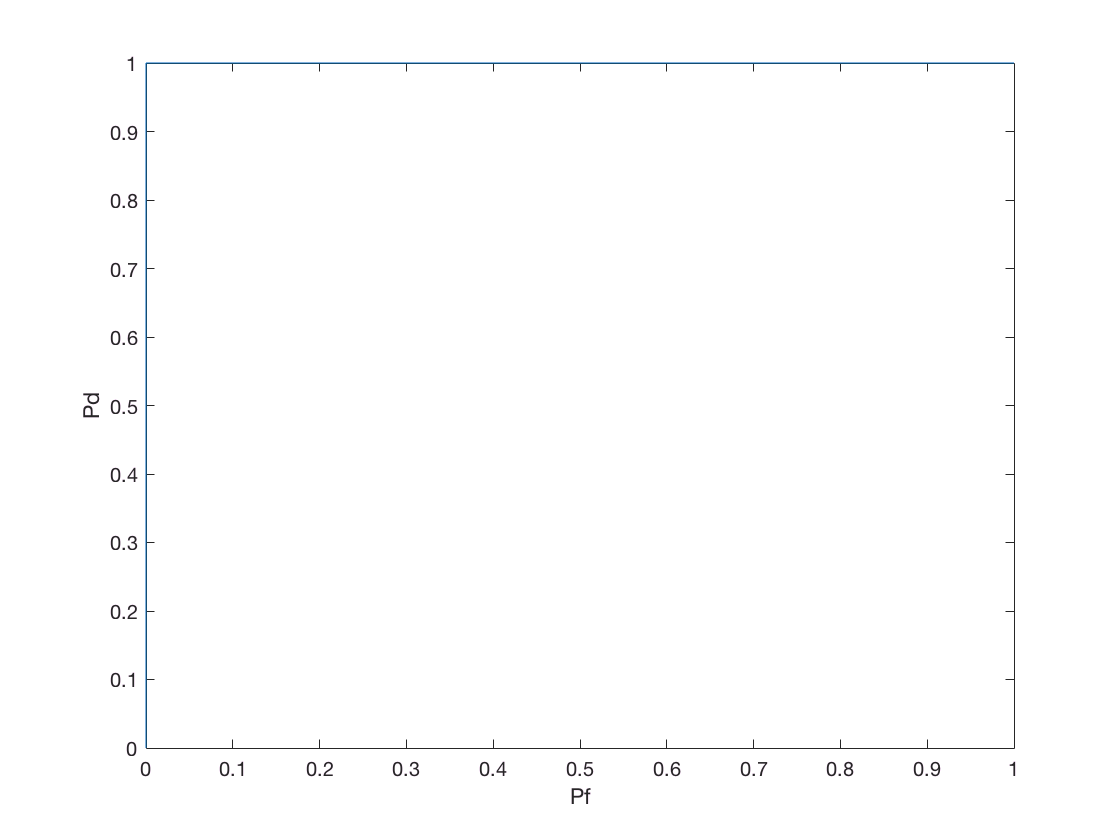

prtScoreRoc(results)

N = ds.nObservations;
k = 4;
keys= [];
for iFold = 1:k 
    keys= cat(1,keys,ones(N/k,1)*iFold);
end
keys = keys(randperm(N))

keys =      2
     1
     2
     4
     3
     2
     4
     3
     1
     3


cls = prtClassFld;
results = prtDataSetClass;

for iFold = 1:k
    ds_train = ds.retainObservations(keys ~= iFold);
    ds_test = ds.retainObservations(keys == iFold);
    ds_test.nObservationsByClass
    cls_trained = cls.train(ds_train);
    results = results.catObservations(cls_trained.run(ds_test));
end 

ans =      4
     6


ans =      7
     3


ans =      5
     5


ans =      4
     6


prtScoreRoc(results)